Uppgift 1.1

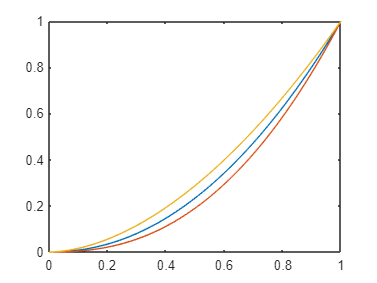

TRC = load("TRC_display.mat");
TRCr = TRC.TRCr;
TRCg = TRC.TRCg;
TRCb = TRC.TRCb;
step = 0:0.01:1;

plot(step, TRCr,step,TRCg, step,TRCb) % Blå röd gul


% Gula(blå kanal) har en större amplitud än dom andra. Blå (röd kanal) är
% starkare än sista (gröna kanalen)
%Leder till mer blått ljus om vi visar ljuset såhär

Uppgift 1.2

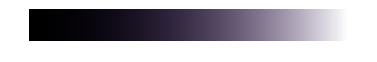

ramp_disp = load("Ramp_display.mat").Ramp_display;
ramp_linear = load("Ramp_linear.mat").Ramp_linear;
TRC = load("TRC_display.mat");
TRCr = TRC.TRCr;
TRCg = TRC.TRCg;
TRCb = TRC.TRCb;    

imshow(ramp_disp); % icke kallibrerad - har en lila tint

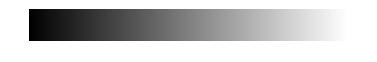

imshow(ramp_linear); % hur den ska se ut när den är kalibrerad

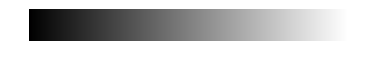


x = 0:0.01:1;
ramp_dispR = interp1(TRCr,x,ramp_disp(:,:,1));
ramp_dispG = interp1(TRCg,x,ramp_disp(:,:,2));
ramp_dispB = interp1(TRCb,x,ramp_disp(:,:,3));
ramp_disp_corr = cat(3,ramp_dispR,ramp_dispG,ramp_dispB);
imshow(ramp_disp_corr); % kallibrerad bild av Ramp_disp

Uppgift 1.3

ramp_disp = load("Ramp_display.mat").Ramp_display;
ramp_linear = load("Ramp_linear.mat").Ramp_linear;

gamR = 2.1; 
gamG = 2.4; 
gamB = 1.8;

Dmax = 1; 
D_x = 0:0.01:1;

DR = Dmax*(ramp_disp(:,:,1)/Dmax).^(1/gamR);
DG = Dmax*(ramp_disp(:,:,2)/Dmax).^(1/gamG);
DB = Dmax*(ramp_disp(:,:,3)/Dmax).^(1/gamB);

step = 0:0.01:1;
%plot(step,DR,step,DG,step,DB); % Blå röd gul 

x = 0:0.01:1;
% ramp_dispR = interp1(x,DR,ramp_disp(:,:,1));
% ramp_dispG = interp1(x,DG,ramp_disp(:,:,2));
% ramp_dispB = interp1(x,DB,ramp_disp(:,:,3));
ramp_disp_corr = cat(3,DR,DG,DB);
imshow(ramp_disp_corr);

Uppgift 2.1

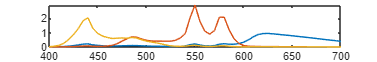

DLP = load("DLP.mat").DLP;
wave = 400:5:700;

plot(wave,DLP(:,1),wave,DLP(:,2),wave,DLP(:,3)); % Blå röd gul (R G B)

% grön starkast, Röd mellan, blå svagast


Uppgift 2.2

load("RGB_raw.mat");
load("DLP.mat");
load("xyz.mat");
load("illum.mat");
load("XYZ_ref.mat");

k = 100./(CIED65*xyz(:,2));
s_rgb= DLP*RGB_raw;
spectrum = xyz'*s_rgb;
observer=spectrum*k;
[L, a, b] =  xyz2lab(observer(1,:)', observer(2,:)', observer(3,:)');
REF_LAB = zeros(3,20);
REF_LAB(1,:) = L;
REF_LAB(2,:) = a;
REF_LAB(3,:) = b;

[L, a, b] =  xyz2lab(XYZ_ref(1,:)', XYZ_ref(2,:)', XYZ_ref(3,:)');
XYZ_ref_lab = zeros(3,20);
XYZ_ref_lab(1,:) = L;
XYZ_ref_lab(2,:) = a;
XYZ_ref_lab(3,:) = b;
% for n=20
%     Edelta(n)= norm(REF_LAB(:,n)-XYZ_ref(:,n))
% end

dE = sqrt((XYZ_ref_lab(1,:)-REF_LAB(1,:)).^2+(XYZ_ref_lab(2,:)-REF_LAB(2,:)).^2+(XYZ_ref_lab(3,:)-REF_LAB(3,:)).^2);


delta_max = max(dE);
delta_mean = mean(dE);
disp("Max: "+delta_max)

Max: 51.638


disp("mean: "+delta_mean)

mean: 22.3508


Uppgift 2.3

load("RGB_cal.mat");
load("DLP.mat");
load("xyz.mat");
load("illum.mat");
load("XYZ_ref.mat");

k = 100./(CIED65*xyz(:,2));
s_rgb= DLP*RGB_cal;
spectrum = xyz'*s_rgb;
observer=spectrum*k;
[L, a, b] =  xyz2lab(observer(1,:)', observer(2,:)', observer(3,:)');
REF_LAB = zeros(3,20);
REF_LAB(1,:) = L;
REF_LAB(2,:) = a;
REF_LAB(3,:) = b;

[L, a, b] =  xyz2lab(XYZ_ref(1,:)', XYZ_ref(2,:)', XYZ_ref(3,:)');
XYZ_ref_lab = zeros(3,20);
XYZ_ref_lab(1,:) = L;
XYZ_ref_lab(2,:) = a;
XYZ_ref_lab(3,:) = b;

dE = sqrt((XYZ_ref_lab(1,:)-REF_LAB(1,:)).^2+(XYZ_ref_lab(2,:)-REF_LAB(2,:)).^2+(XYZ_ref_lab(3,:)-REF_LAB(3,:)).^2);


delta_max = max(dE);
delta_mean = mean(dE);
disp("Max: "+delta_max)

Max: 33.5351


disp("mean: "+delta_mean)

mean: 16.9236


Uppgift 3.1

load("xyz.mat")
load("DLP.mat")
load("illum.mat")

k = 100./(CIED65*xyz(:,2));
A_crt = xyz'*DLP*k; % beskriver färgerna i XYZ


Uppgift 3.2


% A, XYZ_D65_ref och estimate är från lab 1
% input projektor
dependent_input = inv(A_crt)*estimate;

% predict spektral output
S_rgb = DLP*dependent_input;
dependet_spectrum = xyz'*S_rgb;
dependent_output = dependet_spectrum'*k;

[L, a, b] =  xyz2lab(dependent_output(:,1)', dependent_output(:,2)', dependent_output(:,3)');
REF_LAB = zeros(3,20);
REF_LAB(1,:) = L;
REF_LAB(2,:) = a;
REF_LAB(3,:) = b;

[L, a, b] =  xyz2lab(XYZ_D65_ref(1,:)', XYZ_D65_ref(2,:)', XYZ_D65_ref(3,:)');
XYZ_ref_lab = zeros(3,20);
XYZ_ref_lab(1,:) = L;
XYZ_ref_lab(2,:) = a;
XYZ_ref_lab(3,:) = b;

dE = sqrt((XYZ_ref_lab(1,:)-REF_LAB(1,:)).^2+(XYZ_ref_lab(2,:)-REF_LAB(2,:)).^2+(XYZ_ref_lab(3,:)-REF_LAB(3,:)).^2);


delta_max = max(dE);
delta_mean = mean(dE);
disp("Max: "+delta_max)

Max: 3.1053


disp("mean: "+delta_mean)

mean: 1.0238


Uppgift 3.3

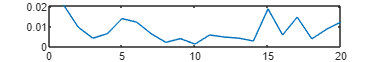


plot(S_rgb(1,:));

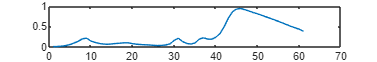

plot(DLP(:,1))

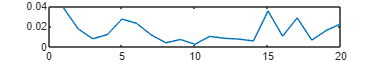


plot(S_rgb(2,:));

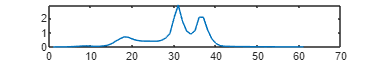

plot(DLP(:,2))

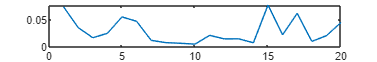


plot(S_rgb(3,:));

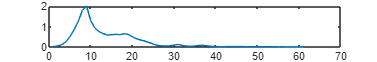

plot(DLP(:,3))

Uppgift 3.4

dependent_input = inv(A_crt)*estimate;
dependent_input(dependent_input>1)=1;
dependent_input(dependent_input<0)=0;

S_rgb_N = DLP*dependent_input;
normalized_spectrum = xyz'*S_rgb_N;
normalized_output = normalized_spectrum'*k;


[L, a, b] =  xyz2lab(normalized_output(:,1)', normalized_output(:,2)', normalized_output(:,3)');
REF_LAB_N = zeros(3,20);
REF_LAB_N(1,:) = L;
REF_LAB_N(2,:) = a;
REF_LAB_N(3,:) = b;

[L, a, b] =  xyz2lab(XYZ_D65_ref(1,:)', XYZ_D65_ref(2,:)', XYZ_D65_ref(3,:)');
XYZ_ref_lab = zeros(3,20);
XYZ_ref_lab(1,:) = L;
XYZ_ref_lab(2,:) = a;
XYZ_ref_lab(3,:) = b;

dE = sqrt((XYZ_ref_lab(1,:)-REF_LAB_N(1,:)).^2+(XYZ_ref_lab(2,:)-REF_LAB_N(2,:)).^2+(XYZ_ref_lab(3,:)-REF_LAB_N(3,:)).^2);


delta_max = max(dE);
delta_mean = mean(dE);
disp("Max: "+delta_max)

Max: 17.874


disp("mean: "+delta_mean)

mean: 2.836


Uppgift 3.5

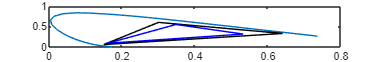

plot_chrom_sRGB(A_crt)

% projektor täcker inte hela rgb spektrum
% Fö2 skala, cutta, ta närmsta värde


Uppgift 3.6

ref_1 = XYZ_D65_ref(:,1);

rep_1 = normalized_output(1,:);

[L, a, b] =  xyz2lab(rep_1(:,1)', rep_1(:,2)', rep_1(:,3)');
REF_LAB_N = zeros(3,1);
REF_LAB_N(1,:) = L;
REF_LAB_N(2,:) = a;
REF_LAB_N(3,:) = b;

[L, a, b] =  xyz2lab(ref_1(1,:)', ref_1(2,:)', ref_1(3,:)');
XYZ_ref_lab = zeros(3,1);
XYZ_ref_lab(1,:) = L;
XYZ_ref_lab(2,:) = a;
XYZ_ref_lab(3,:) = b;

dE = sqrt((XYZ_ref_lab(1,:)-REF_LAB_N(1,:)).^2+(XYZ_ref_lab(2,:)-REF_LAB_N(2,:)).^2+(XYZ_ref_lab(3,:)-REF_LAB_N(3,:)).^2);

disp("dE: " + dE)

dE: 0.033663


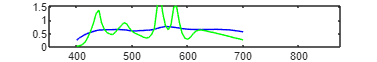


chipxyz = chips20(1,:).*CIED65;
plot(400:5:700, chipxyz, 'blue');
hold on
plot(400:5:700,s_rgb(:,1), 'green')
hold off